# MATLABでのアニメーションの作成

ここでは, MATLABを使ってアニメーションを作成する方法について紹介していきます. もし, 「MATLABって何?」という方は, 「[MATLAB入門](https://jp.mathworks.com/learn/tutorials/matlab-onramp.html)」をお試しください.

このスクリプトの実行方法がわからない方は, [こちらの説明](matlab:open('how_to_use_livescript.mlx'))をお読みください.

このスクリプトで最終的に作成するアニメーションは以下になります.

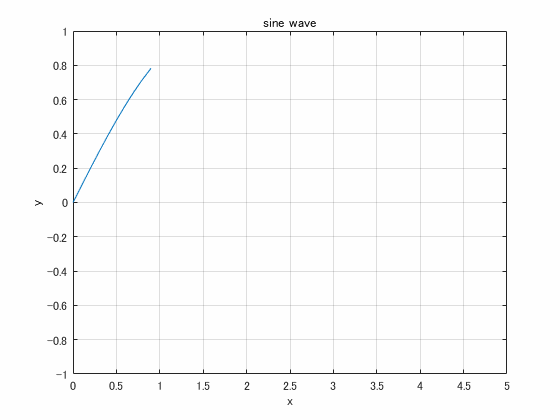

## 初期化

clear; close all; clc;

## グラフ作成の復習

MATLABでアニメーションを作成する前に, MATLABでグラフを作成する方法を復習していきましょう!! 今回は, 以下の式を可視化していきます.


$$y = \sin(x)~~(0\leq x \leq 5)$$


### データの作成

まずは, 可視化するデータが必要になります. そこで, 上の式で示された範囲を0.1ずつに分割したベクトルxと各xでのyの値を求めていきます. （詳しくは「[MATLAB入門](https://jp.mathworks.com/learn/tutorials/matlab-onramp.html)」をやってみてね!!）

x = 0:0.1:5;
y = sin(x);

### 正弦波の可視化

次に, 上で作った(x,y)を可視化してみましょう. 可視化には[plot関数](https://jp.mathworks.com/help/matlab/ref/plot.html)を用います.

figure
plot(x,y);

ここにタイトルやラベルなどの必要な情報も追記していきましょう!!

title("sine wave");
xlim([0 5]); % 0<x<5
ylim([-1 1]); % -1<y<1
xlabel("x");
ylabel("y");
grid on % Show grid

以上が, MATLABにおけるグラフ作成の復習になります. ここから, アニメーションを作成していきます.

## アニメーションの作成

まず, アニメーションはなぜ動くのでしょうか?

それは, 少しずつ異なる静止画を連続で表示させることにより, あたかも, 静止画中の物体が連続的に動いているかのように見せているからです. つまり, 以下を行えば, アニメーションを作成することができます.

- 少しずつ異なる静止画をたくさん用意する.

- 静止画を順番に表示していく

では, 早速, これらを行っていきましょう.

### 少しずつ異なる静止画の作成方法

今回は, 正弦波が少しずつ伸びていくようなアニメーションを作成します. この場合, 正弦波の長さが異なる複数の画像を用意する必要があります. 

ここでは, 既に可視化したグラフを変更していくことで, 長さの異なる正弦波のグラフを作っていきます.

まず, 先ほどと同様に正弦波のグラフを作成します.

figure
p = plot(x,y);
title("sine wave");
xlim([0 5]); % 0<x<5
ylim([-1 1]); % -1<y<1
xlabel("x");
ylabel("y");
grid on

先ほどと1箇所だけ違いますね!! 

だったところが,

となっています. このpは「[ラインのプロパティ](https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html)」と呼ばれており, 

- 何を描画しているか

- どのように描画しているか

というデータが入っています. そして, 描画しているラインのx軸データとy軸データは,XDataとYDataの中に格納されています. 試しに, この2つを変更してみましょう!!

p.XData = x(1:10);
p.YData = y(1:10);
drawnow % Draw the figure now!!

どうでしょう!! 表示範囲が変わりましたね. このようにMATLABではグラフを作成した後にも, そのグラフを変更することができます. そして, [drawnow](https://jp.mathworks.com/help/matlab/ref/drawnow.html?s_tid=doc_ta)を使えば変更した後, すぐに変更後のグラフを見ることができます.

お気づきですか? もう必要なものはすべてそろいました!!

### 静止画を順番に表示していく

では, 正弦波が伸びていくように順番に描画するには, どうすればよいでしょう?

今, xとyには0から5までのx軸の値とそれに対応するsin(x)の値が格納されています. それならば, 表示範囲を1からだんだん大きくしていけば, 線が伸びていくと思いませんか? そして, 表示範囲を変更するごとに[drawnow](https://jp.mathworks.com/help/matlab/ref/drawnow.html?s_tid=doc_ta)で表示していけば, アニメーションが作れるはずです!!

では, [for文](https://jp.mathworks.com/help/matlab/ref/for.html?s_tid=doc_ta)で繰り返しながらやってみましょう!!

for i = 1:length(x)
    p.XData = x(1:i);
    p.YData = y(1:i);
    drawnow
end

どうでしょうか. 目指していたアニメーションは作れましたか?

## おまけ

せっかく作ったアニメーションは保存してみんなに自慢したいですよね.

今, 皆さんが使っている[MATLAB Live Script](https://jp.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html)では, [for文](https://jp.mathworks.com/help/matlab/ref/for.html?s_tid=doc_ta)と[drawnow](https://jp.mathworks.com/help/matlab/ref/drawnow.html?s_tid=doc_ta)を使ってアニメーションを作成すると, figureの右下のアイコン"アニメーションのエクスポート"を押すことで, 簡単に動画を保存することができます.

しかし, これでは動画のスピードや画質を細かく指定することはできません. これらをするには, MATLABの[VideoWriter関数](https://jp.mathworks.com/help/matlab/ref/videowriter.html?s_tid=doc_ta)を使うとできます. 以下がサンプルコードになります（sample.mp4という動画が保存されます）.

v = VideoWriter("sample.mp4",'MPEG-4');
v.Quality = 90;
v.FrameRate = 25;
open(v);
for i = 1:length(x)
    p.XData = x(1:i);
    p.YData = y(1:i);
    frame = getframe(gcf);
    writeVideo(v,frame);
end
close(v);

ぜひ, 魅力的なアニメーションを沢山作ってみてください!!

## 参考文献

- [MATLABによるアニメーション作成 - Qiita](https://qiita.com/tose2125/items/03d9ce40b1b6bde7d36d)

- [ぬめぬめ動く棒グラフ Bar Chart Raceを描いてみよう: 準備編](https://qiita.com/eigs/items/62fbc0b6bdc5e7094abf)

- [このプロットどうやって描いたの？: 複数プロット、アニメーション偏](https://qiita.com/eigs/items/c6efb11c145e4e0e8577)

## [シミュレーション結果の評価に戻る](matlab:open('evaluate_result_jp.mlx'))

## [メニューに戻る](matlab:open('workshopMenu_jp.mlx'))